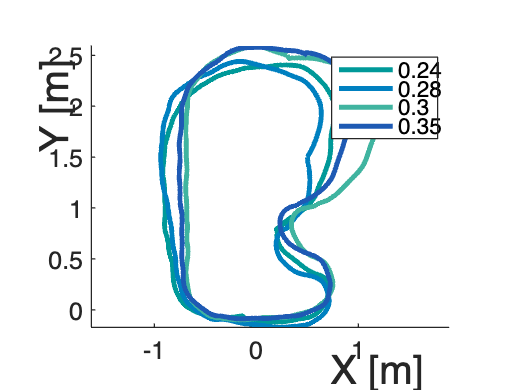

clear; clc; close all;

rec3Chicane = [3490, 3900];

% Identified Laps (Manually Defined)
rec1Lap = [4550, 6720];  
rec2Lap = [2080, 4060]; 
rec3Lap = [1390, 3420]; 
rec4Lap = [100, 1700];  
rec5Lap = [980, 2330; 3585, 5090]; 
rec6Lap = [2140, 3500]; 
rec7Lap = [2220, 3360]; 

lapIntervalsAll = {rec1Lap, rec2Lap, rec3Lap, rec4Lap, rec5Lap(1,:), rec6Lap, rec7Lap};
nRecordings = numel(lapIntervalsAll);  % Ensure consistency

% Initial conditions for each lap
initialTheta = deg2rad([-110; -10; 160; -120; -150; -20; -35]);
initialX = [0.5; 0.5; -0.1; 0.5; 0.5; 0.3; 0.5];
initialY = [1.8; 2.5; -0.1; 1.5; 1.2; 2.5; 2.5];

trajectoryCell = cell(nRecordings, 1);
trgvels = cell(nRecordings, 1);  % Use a cell array for strings

% Reconstruct all trajectories
for recIdx = 1:nRecordings
    dataPath = sprintf('DataSets/rec%d.csv', recIdx);
    [~, timedelta, data] = parseDataSet(dataPath);
    dt = mean(timedelta) * 1e-9;  % Convert nanoseconds to seconds
    
    config = struct();
    lapInterval = lapIntervalsAll{recIdx};
    config.start = lapInterval(1);
    config.stop = lapInterval(2);
    config.heading_subsample = 30;
    config.heading_scale = 0.7;
    config.theta0 = initialTheta(recIdx);
    config.x0 = initialX(recIdx);
    config.y0 = initialY(recIdx);
    
    [x_rec, y_rec, theta_rec, linvel_rec, stats_rec] = mapping(data, dt, config);
    trgvels{recIdx} = num2str(stats_rec.trgtVel);  % Store as string in a cell array
    
    % Close the trajectory loop
    x_rec(end+1) = x_rec(1);
    y_rec(end+1) = y_rec(1);
    
    trajectoryCell{recIdx} = [x_rec, y_rec];
end
colors = [0, 153, 153;   % Deep Cyan
          0, 128, 192;   % Teal Blue
          64, 180, 160;  % Soft Turquoise
          30, 90, 180;   % Ocean Blue
          100, 200, 140; % Mint Green
          50, 120, 80;   % Forest Green
          80, 140, 150] / 255; % Slate Teal


% Plot all the trajectories
fig = figure;
hold on;

traj = trajectoryCell{3};
plot(traj(:,1), traj(:,2), 'Color', colors(1,:), 'LineWidth', 2);
traj = trajectoryCell{4};
plot(traj(:,1), traj(:,2), 'Color', colors(2,:),'LineWidth', 2);
traj = trajectoryCell{6};
plot(traj(:,1), traj(:,2),'Color', colors(3,:),  'LineWidth', 2);
traj = trajectoryCell{7};
plot(traj(:,1), traj(:,2),'Color', colors(4,:),  'LineWidth', 2);

% Customize the plot
xlabel('X [m]','FontSize',16);
ylabel('Y [m]','FontSize',16);
title('Trajectories','FontSize',18 );

legend(trgvels{4:end});  % Convert cell array to legend-compatible format

axis equal;
hold off;

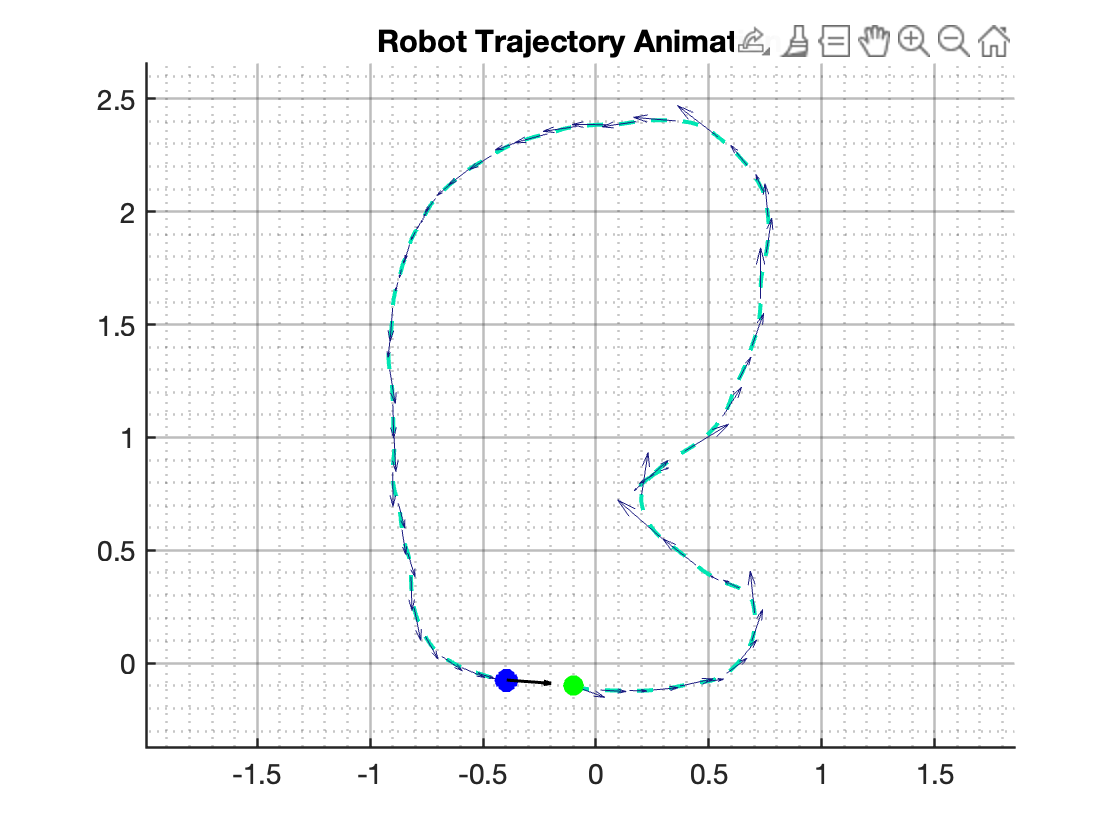

[~, timedelta, data] = parseDataSet('DataSets/rec3.csv');
dt = mean(timedelta*10^-9);
config.start = rec3Lap(1);
config.end = rec3Lap(2);
config.heading_subsample=30;
config.path_line_style = "--";
config.heading_scale = 0.7;
config.theta0 = initialTheta(3);
config.x0 = initialX(3);
config.y0 = initialY(3);
config.colors.path = [0, 0.9, 0.7];
config.colors.heading = [0.1, 0.1, 0.5];

[x, y, theta, linvel, lapstats] = mapping(data,dt,config);

animateTrajectory(x,y,theta,linvel,dt,config)